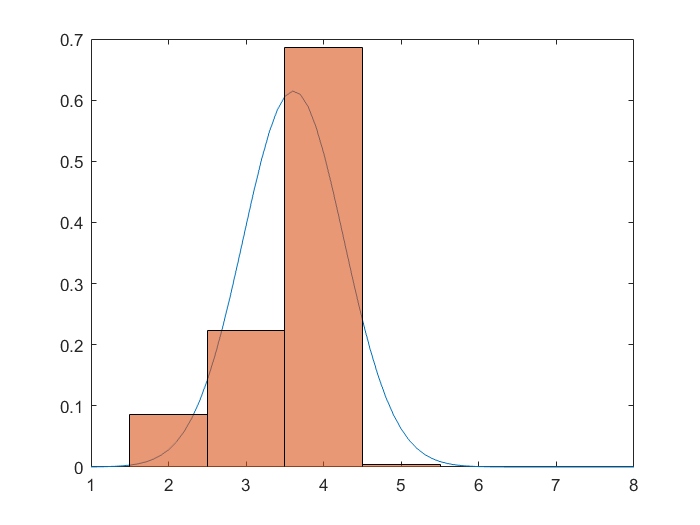

ds = readmatrix("fepB_complete.csv");

ftr = ds(:,2:end-2);
ftr_test = ftr(6,:);
instance_test = [];
outcomes = 1:8;
outcomes1 = 1:0.1:8;

for i = outcomes
    
    val = ftr_test(i);
    vals = zeros([1 val])+i;
    instance_test = [instance_test, vals];
    
end


pd = fitdist(instance_test','normal');
plot(outcomes1,pdf(pd,outcomes1))
hold on
binom_epmf = histogram(instance_test, 'normalization', 'pdf');